clc
clear 
close all

## Functions

function res = centralDifference(x,delta_x)
    res = (x(2)-x(1))/(2*delta_x) ;
end

function res = ShuOsher(phi,psi,delta_x)
    i = 2 ;
    f_pos = 1/2*(phi(i)+phi(i+1))*(psi(i+1)-psi(i))/delta_x ;
    f_neg = 1/2*(phi(i)+phi(i-1))*(psi(i)-psi(i-1))/delta_x ;

    res = (f_pos-f_neg)/delta_x ;
end

## Planar Mixing Layer

% inputs and consts
delta_y = 0.05 ;
delta_t = 1e-3 ;

c_b1 = 0.1355 ;
c_b2 = 0.622 ;
sigma = 2/3 ;

% initializing space and time axes
y = -20:delta_y:20 ;
t = 0:delta_t:100 ;
iy = length(y) ;
it = length(t) ; 

% initializing arrays
u = zeros(1,iy) ;
nu_t = zeros(1,iy) ;
omega = zeros(1,iy) ;
dudt = zeros(1,iy) ;
dnu_tdt = zeros(1,iy) ;

tau_max = zeros(1,it) ;
nu_t_max = zeros(1,it) ;
omega_max = zeros(1,it) ;

% initial conditions 
nu_t(1,:) = 1e-8 ;
u(1,1:find(y==0)) = -1 ;
u(1,find(y==0):iy) = 1 ;

% solver loop
for i = 1:it
    if mod(t(i), 1) == 0
        time = t(i)
    end
    
    if i == find(t==50)
        u_50 = u ;
        nu_t_50 = nu_t ;
        yOmega_max_50 = y*omega_max(i-1) ;
        nu_tOmega_max_50 = nu_t*omega_max(i-1) ;
    elseif i == find(t==100)
        u_100 = u ;
        nu_t_100 = nu_t ;
        yOmega_max_100 = y*omega_max(i-1) ;
        nu_tOmega_max_100 = nu_t*omega_max(i-1) ;
    end

    for j = 2:iy-1
        omega(j) = -centralDifference(u([j-1 j+1]),delta_y) ;  % omega found from central differenceing
        dudt(j) = ShuOsher(nu_t(j-1:j+1),u(j-1:j+1),delta_y) ;
        dnu_tdt(j) = c_b1*abs(omega(j))*nu_t(j) + 1/sigma * ((1+c_b2)*ShuOsher(nu_t(j-1:j+1),nu_t(j-1:j+1),delta_y) - c_b2 * nu_t(j) * ShuOsher([1 1 1],nu_t(j-1:j+1),delta_y)) ;
    end
    
    tau_max(i) = max(abs(-nu_t.*omega)) ;
    nu_t_max(i) = max(nu_t) ;
    omega_max(i) = max(abs(omega)) ;

    u = u+ delta_t*dudt ;
    nu_t = nu_t + delta_t*dnu_tdt ;
end

time = 0

time = 1

time = 2

time = 3

time = 4

time = 5

time = 6

time = 7

time = 8

time = 9

time = 10

time = 11

time = 12

time = 13

time = 14

time = 15

time = 16

time = 17

time = 18

time = 19

time = 20

time = 21

time = 22

time = 23

time = 24

time = 25

time = 26

time = 27

time = 28

time = 29

time = 30

time = 31

time = 32

time = 33

time = 34

time = 35

time = 36

time = 37

time = 38

time = 39

time = 40

time = 41

time = 42

time = 43

time = 44

time = 45

time = 46

time = 47

time = 48

time = 49

time = 50

time = 51

time = 52

time = 53

time = 54

time = 55

time = 56

time = 57

time = 58

time = 59

time = 60

time = 61

time = 62

time = 63

time = 64

time = 65

time = 66

time = 67

time = 68

time = 69

time = 70

time = 71

time = 72

time = 73

time = 74

time = 75

time = 76

time = 77

time = 78

time = 79

time = 80

time = 81

time = 82

time = 83

time = 84

time = 85

time = 86

time = 87

time = 88

time = 89

time = 90

time = 91

time = 92

time = 93

time = 94

time = 95

time = 96

time = 97

time = 98

time = 99

time = 100

## Planar Mixing Layer Plots

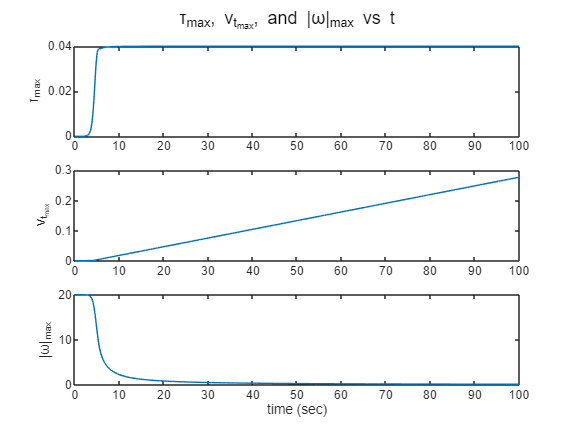

figure
subplot(3,1,1)
plot(t,tau_max)
ylabel('τ_m_a_x')
subplot(3,1,2)
plot(t,nu_t_max)
ylabel('ν_{t_m_a_x}')
subplot(3,1,3)
plot(t,omega_max)
ylabel('|ω|_m_a_x')
xlabel('time (sec)')
sgtitle('τ_m_a_x, ν_{t_m_a_x}, and |ω|_m_a_x vs t')

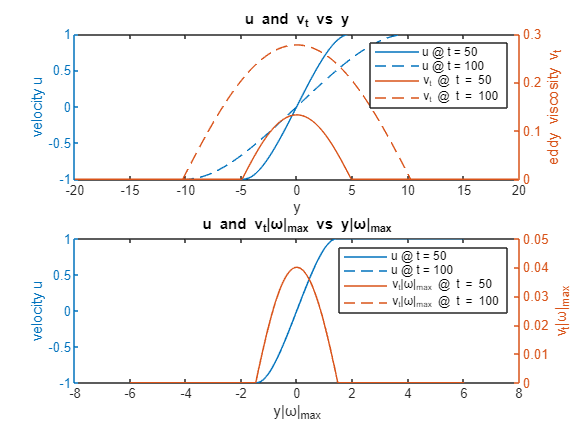


figure
subplot(2,1,1)
yyaxis left
plot(y,u_50,y,u_100)
ylabel('velocity u')
yyaxis right
plot(y,nu_t_50,y,nu_t_100)
ylabel('eddy viscosity ν_t')
legend('u @ t = 50','u @ t = 100','ν_t @ t = 50','ν_t @ t = 100')
xlabel('y')
title('u and ν_t vs y')
subplot(2,1,2)
yyaxis left
plot(yOmega_max_50,u_50,yOmega_max_100,u_100)
ylabel('velocity u')
yyaxis right
plot(yOmega_max_50,nu_tOmega_max_50,yOmega_max_100,nu_tOmega_max_100)
ylabel('ν_t|ω|_m_a_x')
legend('u @ t = 50','u @ t = 100','ν_t|ω|_m_a_x @ t = 50','ν_t|ω|_m_a_x @ t = 100')
xlabel('y|ω|_m_a_x')
title('u and ν_t|ω|_m_a_x vs y|ω|_m_a_x')

## Planar Wake